# *%% PROGETTO: VISUALIZZAZIONE 3D DI SEQUENZE REALI DI DNA E STRUTTURA TABELLA*

#### %% Corso: Fondamenti di Informatica - Prof. Luca D'Agati

clear; clc; close all;


%% 1. DOWNLOAD DATI REALI DA NCBI ED ESPRESSIONE REGOLARE  (Acquisizione API HTTP)

disp('Connessione al database scientifico NCBI in corso...');

Connessione al database scientifico NCBI in corso...



% Configurazione parametri di rete
baseURL = 'https://eutils.ncbi.nlm.nih.gov/entrez/eutils/';
opts = weboptions('Timeout', 30);

% Identificativo NCBI per il gene dell'Insulina Umana 
id_insulina = 'NM_000618'; 

% Costruzione dell'URL per scaricare il record in formato testo (FASTA)
fetchURL = [baseURL 'efetch.fcgi?db=nuccore&id=' id_insulina '&rettype=fasta&retmode=text'];

try
    % Scaricamento dati reali via webread 
    data_grezza = webread(fetchURL, opts);
    disp('Dati scaricati correttamente da NCBI.');
    
    % Pulizia del testo: elimino l'intestazione che inizia con '>'
    righe = splitlines(data_grezza);
    sequenza_letta = ''; %creo una stringa vuota (che ancora non contiene nulla) 
    for r = 2:length(righe)
        sequenza_letta = [sequenza_letta, upper(trimwhitespace(righe{r}))]; %#ok<AGROW>  --> il risultato sara' una stringa continua di tipo ATCGGCTAA..
    end
    
    % Isolo le prime 45 basi per una visualizzazione grafica pulita
    sequenza_reale = sequenza_letta(1:45);
    
catch
    % Alternativa offline se internet o il server NCBI non dovessero funzionare
    disp('Attenzione: Server NCBI non raggiungibile. Caricamento sequenza locale.');
    sequenza_reale = 'AGCCCTCCAGGACAGGCTGCATCAGAAGAGGCCATCAAGCAGGT'; 
end

Dati scaricati correttamente da NCBI.


Attenzione: Server NCBI non raggiungibile. Caricamento sequenza locale.



% --- VERIFICA TRAMITE ESPRESSIONE REGOLARE 

% Il pattern '[^ATCG]' cerca qualsiasi carattere che NON sia una base valida.
if ~isempty(regexp(sequenza_reale, '[^ATCG]', 'once'))
    error('Errore Critico: La sequenza contiene caratteri non validi per il DNA!');
else
    disp('Verifica Regex Superata: La stringa analizzata è un DNA valido.');
    fprintf('Sequenza analizzata: %s\n\n', sequenza_reale);
end

Verifica Regex Superata: La stringa analizzata è un DNA valido.


Sequenza analizzata: AGCCCTCCAGGACAGGCTGCATCAGAAGAGGCCATCAAGCAGGT




N_basi = length(sequenza_reale);


%% 2. CONFIGURAZIONE GEOMETRICA E GRAFICA DELLA DOPPIA ELICA

% Dominio dell'elica per il tracciamento continuo (parametro t), che
% controlla la spirale
t = linspace(0, 6*pi, 1000);

% Geometria della prima elica (Filamento A)
x1 = cos(t);   
y1 = sin(t);   
z1 = linspace(0, 15, 1000); % Altezza progressiva

% Geometria della seconda elica (Filamento B sfasato di pi greco)
x2 = cos(t + pi);
y2 = sin(t + pi);
z2 = z1;

% Creazione figura con sfondo scuro
figure('Color', [0.1 0.1 0.1]); 
hold on; 

% Disegno dei filamenti bianchi esterni -> unisco i 1000 punti
plot3(x1, y1, z1, 'w', 'LineWidth', 2.5); 
plot3(x2, y2, z2, 'w', 'LineWidth', 2.5); 


%% 3. PREPARAZIONE VETTORI PER LA TABELLA DEI DATI (Progettazione Database)

% Preparo dei vettori vuoti in cui salveremo i dati ad ogni ciclo.
% Questo serve per costruire la tabella finale (il "database").
vettore_ID = (1:N_basi)';
vettore_BaseSup = cell(N_basi, 1);
vettore_BaseInf = cell(N_basi, 1);
vettore_X = zeros(N_basi, 1);
vettore_Y = zeros(N_basi, 1);
vettore_Z = zeros(N_basi, 1);


%% 4. ELABORAZIONE BIOLOGICA, GRAFICA E RACCOLTA DATI

%Stabilisco l'altezza verticale delle basi e la loro posizione angolare
z_basi = linspace(0.2, 14.8, N_basi);
t_basi = linspace(0, 6*pi, N_basi);

lista_colori = 'gmcy'; % g=Verde (A), m=Magenta (T), c=Ciano (C), y=Giallo (G)
nomi_basi = 'ATCG'; 

for i = 1:N_basi
    % Prendo la base corrente dalla sequenza reale
    base_sopra = sequenza_reale(i);
    
    % Regola di Watson-Crick per la base inferiore
    if base_sopra == 'A',     base_sotto = 'T';
    elseif base_sopra == 'T', base_sotto = 'A';
    elseif base_sopra == 'C', base_sotto = 'G';
    else,                     base_sotto = 'C';
    end 
    
    %ricerco l'indice del colore -> quindi la posizione della base nella
    %stringa 'ATCG'
    idx_sopra = strfind(nomi_basi, base_sopra);
    idx_sotto = strfind(nomi_basi, base_sotto);

    % Coordinate spaziali delle basi
    xa = cos(t_basi(i));
    ya = sin(t_basi(i));
    za = z_basi(i);
    
    xb = cos(t_basi(i) + pi);
    yb = sin(t_basi(i) + pi);
    zb = z_basi(i);
    
    % Punto medio per i legami
    xm = (xa + xb) / 2;
    ym = (ya + yb) / 2;
    zm = (za + zb) / 2;

    % --- Grafica ---
    plot3(xa, ya, za, 'wo', 'MarkerFaceColor', 'w', 'MarkerSize', 5); %disegno le sferette bianche
    plot3(xb, yb, zb, 'wo', 'MarkerFaceColor', 'w', 'MarkerSize', 5); 

    text(xa * 1.15, ya * 1.15, za, base_sopra, 'Color', 'w', 'FontSize', 8, 'HorizontalAlignment', 'center');
    text(xb * 1.15, yb * 1.15, zb, base_sotto, 'Color', 'w', 'FontSize', 8, 'HorizontalAlignment', 'center');

    plot3([xa, xm], [ya, ym], [za, zm], lista_colori(idx_sopra), 'LineWidth', 2); %disegno i pioli
    plot3([xm, xb], [ym, yb], [zm, zb], lista_colori(idx_sotto), 'LineWidth', 2); 
    
    % --- Salvataggio temporaneo nei vettori ---
    vettore_BaseSup{i} = base_sopra;
    vettore_BaseInf{i} = base_sotto;
    vettore_X(i) = xa;
    vettore_Y(i) = ya;
    vettore_Z(i) = za;
end


%% 5. RIFINITURA DEL GRAFICO 3D

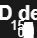

grid on; 
view(3); 
axis equal; 
title('Modello Molecolare 3D del DNA (Dati Reali NCBI)', 'Color', 'w', 'FontSize', 12); 
xlabel('Asse X', 'Color', 'w'); 
ylabel('Asse Y', 'Color', 'w'); 
zlabel('Asse Z (Altezza)', 'Color', 'w'); 
set(gca, 'Color', [0.1 0.1 0.1], 'XColor', 'w', 'YColor', 'w', 'ZColor', 'w');

drawnow;


%% 6. CREAZIONE DELLA TABELLA E SALVATAGGIO DATI 

% Costruisco la tabella MATLAB combinando tutti i vettori riempiti nel ciclo
TabellaDNA = table(vettore_ID, vettore_BaseSup, vettore_BaseInf, vettore_X, vettore_Y, vettore_Z, ...
    'VariableNames', {'ID', 'BaseSuperiore', 'BaseInferiore', 'CoordinataX', 'CoordinataY', 'CoordinataZ'});

fprintf('\n==================================================\n');

disp('STRUTTURA DELLA TABELLA DATI REALIZZATA (Primi 10 record):');

STRUTTURA DELLA TABELLA DATI REALIZZATA (Primi 10 record):


fprintf('==================================================\n');

disp(TabellaDNA(1:10, :)); % Mostra le prime 10 righe della tabella

    ID    BaseSuperiore    BaseInferiore    CoordinataX    CoordinataY    CoordinataZ
    __    _____________    _____________    ___________    ___________    ___________

     1        {'A'}            {'T'}                1              0            0.2  
     2        {'G'}            {'C'}          0.90545        0.42446        0.53953  
     3        {'C'}            {'G'}          0.63967        0.76865        0.87907  
     4        {'C'}            {'G'}          0.25293        0.96748         1.2186  
     5        {'C'}            {'G'}         -0.18164        0.98337         1.5581  
     6        {'T'}            {'A'}         -0.58186        0.81329         1.8977  
     7        {'C'}            {'G'}         -0.87205        0.48942         2.2372  
     8        {'C'}  


% Salvo la tabella in un file di database MATLAB (.mat) sul PC
save('Database_DNA_Progetto.mat', 'TabellaDNA');
disp('Tabella salvata correttamente nel file locale "Database_DNA_Progetto.mat".');

Tabella salvata correttamente nel file locale "Database_DNA_Progetto.mat".


%% 7. DATA FILTERING INTERATTIVO -> Interfaccia grafica (GUI)

fprintf('\n==================================================\n');

disp('QUERY SCELTA DALL UTENTE: ');

QUERY SCELTA DALL UTENTE: 



%INTRODUCO UN LIVE EDITOR CONTROL
% Seleziona la base da filtrare direttamente dal menu a tendina:
base_scelta = "A"; 

% Interrogazione dinamica della tabella in base alla scelta dell'utente
RigheFiltrate = TabellaDNA(strcmp(TabellaDNA.BaseSuperiore, base_scelta), :);
disp(RigheFiltrate);

    ID    BaseSuperiore    BaseInferiore    CoordinataX    CoordinataY    CoordinataZ
    __    _____________    _____________    ___________    ___________    ___________

     1        {'A'}            {'T'}                 1              0          0.2   
     9        {'A'}            {'T'}          -0.93402       -0.35723       2.9163   
    12        {'A'}            {'T'}           0.10937         -0.994       3.9349   
    14        {'A'}            {'T'}             0.834       -0.55177        4.614   
    21        {'A'}            {'T'}           -0.7915        0.61117       6.9907   
    24        {'A'}            {'T'}           -0.7915       -0.61117       8.0093   
    26        {'A'}            {'T'}         -0.036522       -0.99933       8.6884   
    27        {'A'}  

%% 8. INTEGRAZIONE DATABASE SQLITE ESTERNO

fprintf('\n==================================================\n');

disp('INTEGRAZIONE CON DATABASE RELAZIONALE ESTERNO (SQLite):');

INTEGRAZIONE CON DATABASE RELAZIONALE ESTERNO (SQLite):



%definisco una variabile di testo il nome del file del database reale
nome_db = 'Database_DNA_SQLite.db';

% Se esiste già un vecchio file con lo stesso nome, lo cancello per aggiornarlo
if exist(nome_db, 'file')
    delete(nome_db);
end

% 1. Connessione/Creazione fisica del file di Database SQLite VUOTO
conn = sqlite(nome_db, 'create');

% 2. Esportazione e Scrittura della tabella MATLAB dentro il Database SQLite
sqlwrite(conn, 'SequenzeDNA', TabellaDNA);
disp('Tabella "SequenzeDNA" esportata con successo nel Database SQLite permanente.');

Tabella "SequenzeDNA" esportata con successo nel Database SQLite permanente.



% 3. Interrogazione del database reale tramite linguaggio nativo SQL standard
query_SQL = 'SELECT ID, BaseSuperiore, BaseInferiore FROM SequenzeDNA WHERE BaseSuperiore = "C"';
RisultatoSQL = fetch(conn, query_SQL);

disp('Risultato della Query SQL (Estratte solo le Citosine "C" con relativi ID):');

Risultato della Query SQL (Estratte solo le Citosine "C" con relativi ID):


disp(RisultatoSQL);

    ID    BaseSuperiore    BaseInferiore
    __    _____________    _____________

     3         "C"              "G"     
     4         "C"              "G"     
     5         "C"              "G"     
     7         "C"              "G"     
     8         "C"              "G"     
    13         "C"              "G"     
    17         "C"              "G"     
    20         "C"              "G"     
    23         "C"              "G"     
    32         "C"              "G"     
    33         "C"              "G"     
    36         "C"              "G"     
    40         "C"              "G"     




% 4. Chiusura formale della connessione al Database
close(conn);
disp('Connessione al Database SQLite chiusa correttamente.');

Connessione al Database SQLite chiusa correttamente.
